% -----------------------------------------
% Assignment for linear equations
% LiXin
% 2022/3/18
% -----------------------------------------

Problem 1

(a)

clear; close all; clc;
A=[2 1; 3 -9];
b=[5; 7];
rankA=rank(A)

rankA = 2

rank(A)==rank([A b])

ans = logical
   1


sol=A\b;
fprintf("x=%f y=%f", sol(1), sol(2))

x=2.476190 y=0.047619

(b)

clear; close all; clc;
A=[-8 -5; -2 7];
b=[4; 10];
rankA=rank(A)

rankA = 2

rank(A)==rank([A b])

ans = logical
   1


sol=A\b;
fprintf("x=%f y=%f", sol(1), sol(2))

x=-1.181818 y=1.090909

(c)

clear; close all; clc;
A=[12 -5 0; -3 4 7; 6 2 3];
b=[11; -3; 22];
rankA=rank(A)

rankA = 3

rank(A)==rank([A b])

ans = logical
   1


sol=A\b;
fprintf("x=%f y=%f x3=%f",sol(1), sol(2), sol(3))

x=3.000000 y=5.000000 x3=-2.000000

(d)

clear; close all; clc;
A=[6 -3 4; 12 5 -7; -5 2 6];
b=[41; -26; 16];
rankA=rank(A)

rankA = 3

rank(A)==rank([A b])

ans = logical
   1


sol=A\b;
fprintf("x=%f y=%f x3=%f", sol(1), sol(2), sol(3))

x=2.003503 y=-2.684764 x3=5.231173

Problem 2

(a)

clear; close all; clc;

C=inv(B)inv(A)B-inv(B)A

(b)

A=[7 9; -2 4];
B=[4 -3; 7 6];
C=inv(B)*inv(A)*B-inv(B)*A

C =    -0.8536   -1.6058
    1.5357    1.3372


Problem 3

(a)

clear; close all; clc;
A=[-2 1; -2 1];
b=[-5; 3];
rank_A=rank(A)

rank_A = 1

rank([A b])

ans = 2

因为A的秩小于[A b]的秩，所以方程无解

用最小二乘法解

sol=lsqr(A,b)

lsqr converged at iteration 1 to a solution with relative residual 0.97.


sol =     0.4000
   -0.2000


fprintf("x'=%f y'=%f",sol(1),sol(2))

x'=0.400000 y'=-0.200000

(b)

clear; close all; clc;
A=[-2 1; -8 4];
b=[3; 12];
rank_A=rank(A)

rank_A = 1

rank([A b])

ans = 1

方乘有无限解

用pinv()

sol=pinv(A)*b

sol =    -1.2000
    0.6000


用'\'

sol=A\b

sol =    NaN
   NaN


用rref()

rref([A b])

ans =     1.0000   -0.5000   -1.5000
         0         0         0


x=-1.5+0.5y

(c)

clear; close all; clc;
A=[-2 1; -2 1];
b=[-5; -5.00001];
rankA=rank(A)

rankA = 1

rank([A b])

ans = 2

方程无解，使用最小二乘法

sol=lsqr(A,b)

lsqr converged at iteration 1 to a solution with relative residual 1e-06.


sol =     2.0000
   -1.0000


(d)

clear; close all; clc;
A=[1 5 -1 6; 2 -1 1 -2; -1 4 -1 3; 3 -7 -2 1];
b=[19; 7; 30; -75];
rank_A=rank(A)

rank_A = 4

rank([A b])

ans = 4

x=A\b

x =     5.0000
   14.6250
  -12.1250
  -11.8750


Problem 4

(a)

syms x y z c
eqns=[x-5*y-2*z==11*c; 6*x+3*y+z==13*c; 7*x+3*y-5*z==10*c];
sol=solve(eqns,[x y z]);
x=sol.x

$$x = 3\,c$$

y=sol.y

$$y = -2\,c$$

z=sol.z

$$z = c$$

(b)

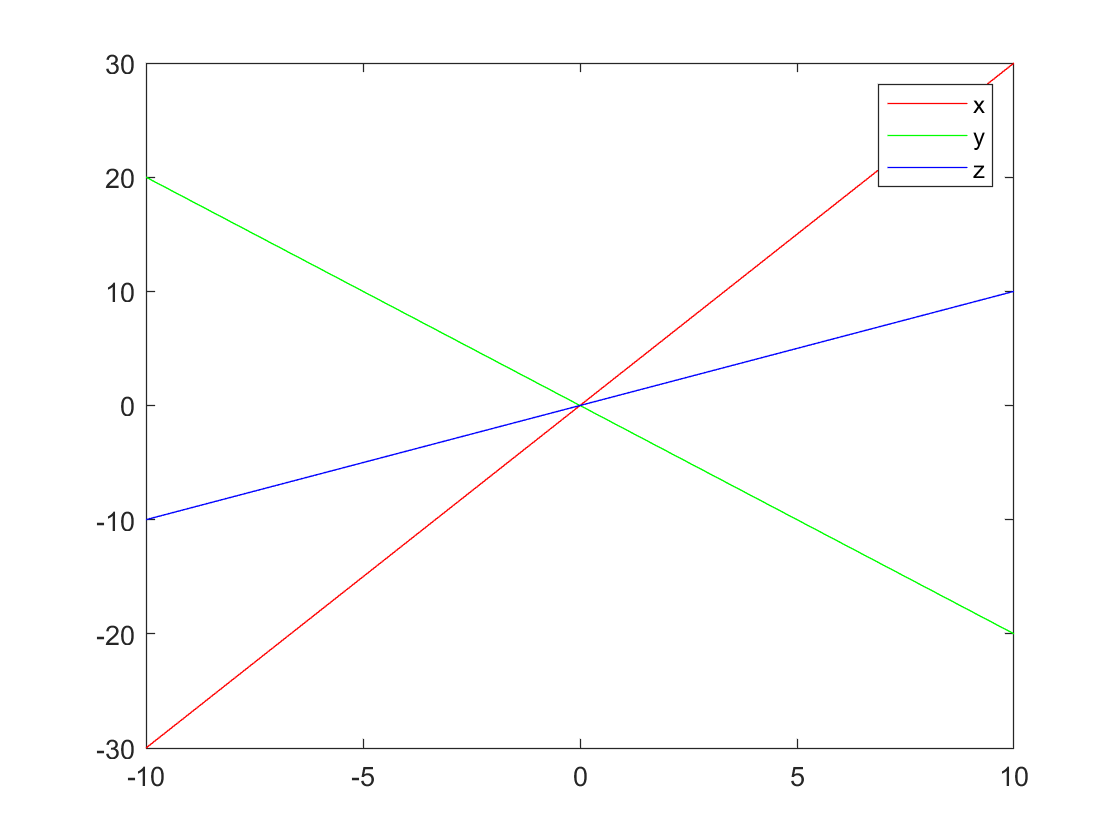

c=-10:0.1:10;
sol=subs(sol);
plot(c,sol.x,'r',c,sol.y,'g',c,sol.z,'b')
legend('x','y','z')

Problem 5

(a)

clear; close; clc;
% for coeffcients a1, a2, a3
syms theta1_0 theta1_tf tf a1 a2 a3 rhs1 a
A1=[tf^3 tf^4 tf^5;3*tf^2 4*tf^3 5*tf^4; 6*tf 12*tf^2 20*tf^3];
a=[a1;a2;a3];
rhs1=[theta1_tf-theta1_0;0;0];
eqn1=A1*a==rhs1

$$eqn1 = \left(\begin{array}{c} a_{3}\,{\mathrm{tf}}^{5}+a_{2}\,{\mathrm{tf}}^{4}+a_{1}\,{\mathrm{tf}}^{3}=\theta_{1,\mathrm{tf}}-\theta_{1,0}\\ 5\,a_{3}\,{\mathrm{tf}}^{4}+4\,a_{2}\,{\mathrm{tf}}^{3}+3\,a_{1}\,{\mathrm{tf}}^{2}=0\\ 20\,a_{3}\,{\mathrm{tf}}^{3}+12\,a_{2}\,{\mathrm{tf}}^{2}+6\,a_{1}\,\mathrm{tf}=0 \end{array}\right)$$


% for coefficients b1, b2, b3
syms theta2_0 theta2_tf b1 b2 b3 rhs2 b
A2=[tf^3 tf^4 tf^5; 3*tf^2 4*tf^3 5*tf^4; 6*tf 12*tf^2 20*tf^3];
b=[b1;b2;b3];
rhs2=[theta2_tf-theta2_0;0;0];
eqn2=A2*b==rhs2

$$eqn2 = \left(\begin{array}{c} b_{3}\,{\mathrm{tf}}^{5}+b_{2}\,{\mathrm{tf}}^{4}+b_{1}\,{\mathrm{tf}}^{3}=\theta_{2,\mathrm{tf}}-\theta_{2,0}\\ 5\,b_{3}\,{\mathrm{tf}}^{4}+4\,b_{2}\,{\mathrm{tf}}^{3}+3\,b_{1}\,{\mathrm{tf}}^{2}=0\\ 20\,b_{3}\,{\mathrm{tf}}^{3}+12\,b_{2}\,{\mathrm{tf}}^{2}+6\,b_{1}\,\mathrm{tf}=0 \end{array}\right)$$

(b)

tf=2;
theta1_0=-19;
theta2_0=44;
theta1_tf=43;
theta2_tf=151;
A1=subs(A1);
rhs1=subs(rhs1);
p1=A1\rhs1;
fprintf("a1=%f a2=%f a3=%f",p1(1),p1(2),p1(3))

a1=77.500000 a2=-58.125000 a3=11.625000

A2=subs(A2);
rhs2=subs(rhs2);
p2=A2\rhs2;
fprintf("b1=%f b2=%f b3=%f",p2(1),p2(2),p2(3))

b1=133.750000 b2=-100.312500 b3=20.062500

(c)

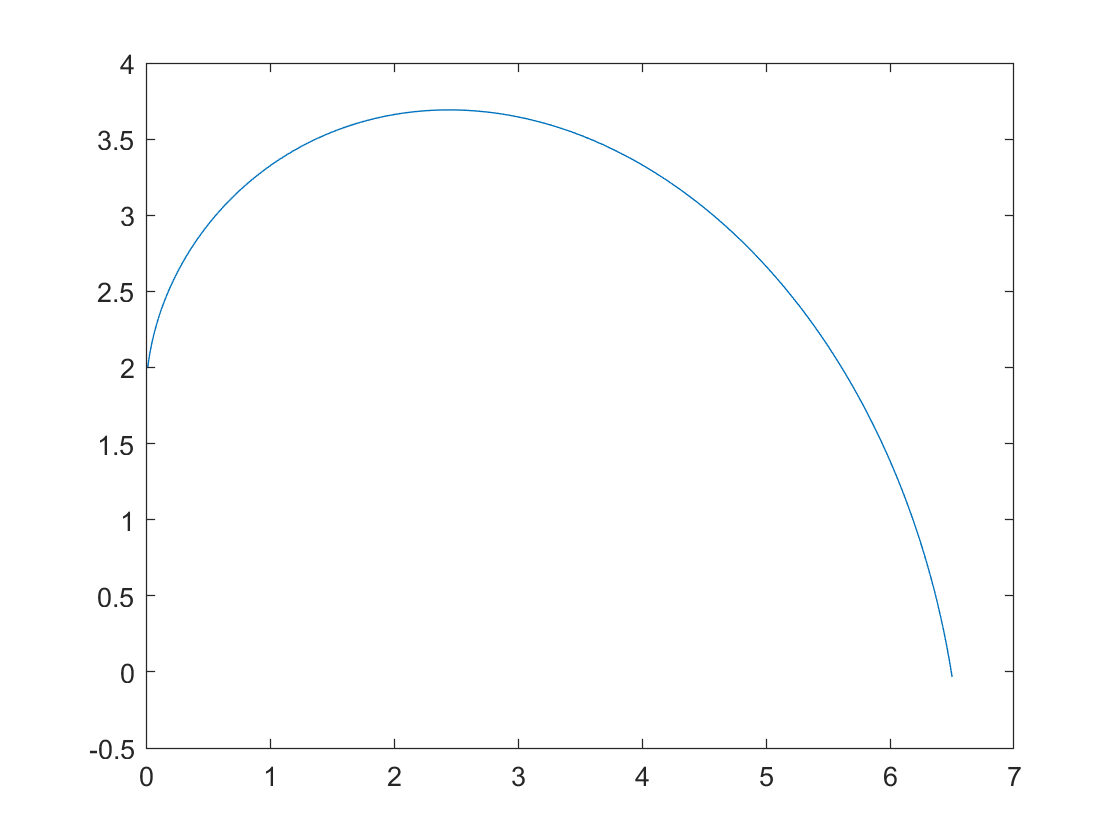

t=0:0.01:2;
t=t';
A=[t.^3 t.^4 t.^5];
theta1=theta1_0+A*p1;
theta2=theta2_0+A*p2;
L1=4; L2=3;
x=L1*cos(deg2rad(theta1))+L2*cos(deg2rad(theta1+theta2));
y=L1*sin(deg2rad(theta1))+L2*sin(deg2rad(theta1+theta2));
plot(x,y)

Problem 6

clear; close; clc;
Ti=20;
To=-10;
R1=0.036*10;
R2=4.01*10;
R3=0.408*10;
R4=0.038*10;
syms q T1 T2 T3
eqns=[q==1/R1*(Ti-T1); q==1/R2*(T1-T2); q==1/R3*(T2-T3); q==1/R4*(T3-To)];
S=solve(eqns,[q T1 T2 T3]);
fprintf("q=%f T1=%f T2=%f T3=%f", S.q, S.T1, S.T2, S.T3)

q=0.667854 T1=19.759573 T2=-7.021371 T3=-9.746215